**ESTIMATION OF FRICTION PARAMETERS**

In this part its is necessary to load the data obtained from the stair input sequence with $\Delta =50\;$rpm. We need to import data both for the positive and negative stair. 

Pay al lot of attention when saving the output!! Use the correct name and *rename OUT*.

Each operation must be repeated both for postive and negative stair sequence

clear all
clc

load('parameters.mat')
load('Simulations\positive_stair.mat')
load('Simulations\negative_stair.mat')

**Butterwoth high-pass filter **

In this case it is used to filter the current

filt.wci = 2*pi*20;
filt.di = 1/sqrt(2);
sysHi = tf(filt.wci^2,[1 2*filt.di*filt.wci filt.wci^2]);
sysHi = c2d(sysHi, Ts, 'tustin');
[numHi, denHi] =tfdata(sysHi, 'v');

Current filtering

proc.iaf_positive = filter(numHi, denHi, positive_stair.ia.Data);
proc.iaf_negative = filter(numHi, denHi, negative_stair.ia.Data);

Quantities needed fot the estimation (wrt motor, measured ones are wrt load)   

*CHECK* - ia plot

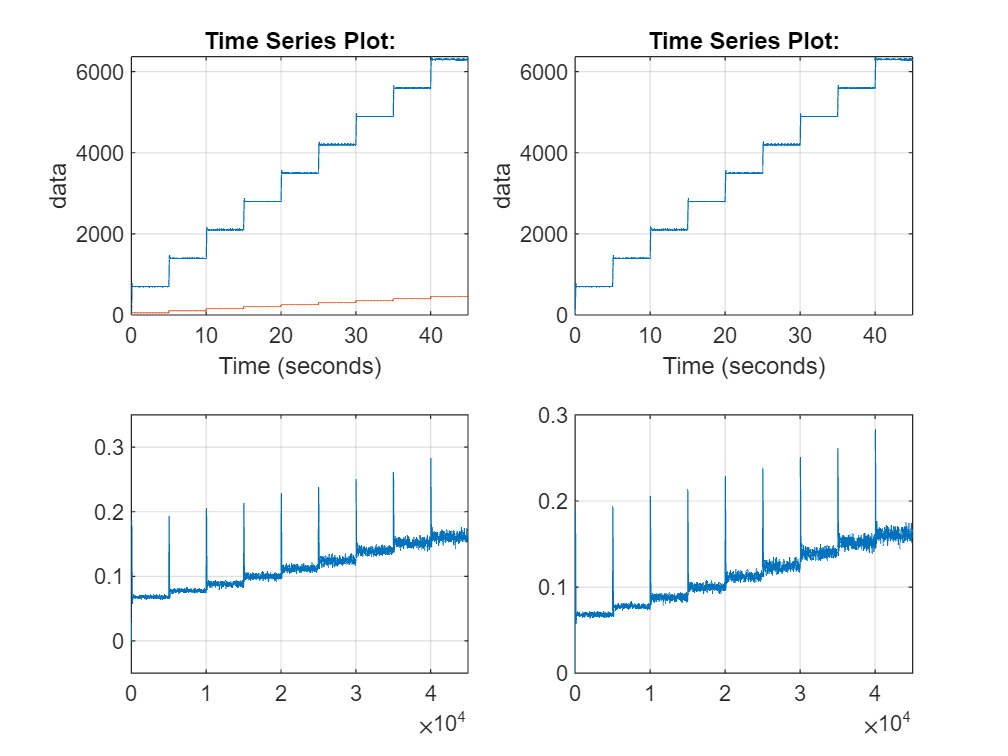

proc.wm_positive = gbox.N*positive_stair.wl_meas;
proc.taum_positive = mot.Kt*proc.iaf_positive;

proc.wm_negative = gbox.N*negative_stair.wl_meas;
proc.taum_negative = mot.Kt*proc.iaf_negative; 

% Figures to check everithing is ok
figure;
subplot(2,2,1);
plot(proc.wm_positive);
hold on
plot(positive_stair.wref)
grid on;
subplot(2,2,3);
plot(proc.iaf_positive);
grid on;
axis([0 45000 -0.05 0.35])
subplot(2,2,2);
plot(proc.wm_negative);
grid on;
subplot(2,2,4);
plot(proc.iaf_negative);
grid on;

**Least Squares Estimation **

Repeat the estimate both for positive and negative data. Then take the average value.   

TOFIX:     we tested the function with old data. it is not possible to test the mean due to variable step solver

est.phi_positive = zeros(9,2);
est.phi_negative = zeros(9,2);
est.Y_positive = zeros(9, 1);
est.Y_negative = zeros(9, 1);

% Estimation of the average values
for i=1:9
    ind = 5000*(i-1)+200:5000*(i-1)+800;
    % Positive reference
    est.phi_positive(i,1) = mean(proc.wm_positive(ind));
    est.phi_postive(i,2) = 1/gbox.N*sign(est.phi_postive(1,i));
    est.Y_positive(i) = mean(proc.iaf_positive(ind)); 
    % Negative reference
    est.phi_negative(i,1) = mean(proc.wm_negative(ind));
    est.phi_negative(i,2) = 1/gbox.N*sign(est.phi_negative(1,i));
    est.Y_negative(i) = mean(proc.iaf_negative(ind));
end

Index exceeds the number of array elements. Index must not exceed 1.


est.theta_positive = ((est.phi_positive.'*est.phi_positive)^-1)*est.phi_positive.'*est.Y_positive
est.theta_negative = ((est.phi_negative.'*est.phi_negative)^-1)*est.phi_negative.'*est.Y_negative

Estiamtion of the average values between the two cases

friction.Beq = 0.5*(est.theta_positive(1)+est.theta_negative(1));
friction.tausf = 0.5*(abs(est.theta_positive(2))+abs(est.theta_negative(2)));

save('friction_est.mat',"friction")

Friciton torque plot (motor speed [krpm])

TODO

**Estimate of the covariance matrix of the LS solution**

TODO --> Grim this is for you sistema con media etc

est.theta_LS = [friction.Beq; friction.tausf];
est.phi = (est.phi_positive + abs(est.phi_negative))/2; %probably it doesn't make any sense
est.Y = (est.Y_positive + abs(Y_negative))/2;
est.V_theta_LS = (est.Y- est.phi*est.theta_LS).'*(est.Y- est.phi*est.theta_LS);
est.lambda2 = 1/(2-9)*est.V_theta_LS;     %9-2 = M - p  M number of measurement p param estimated
est.cov_theta_LS = est.lambda2*(est.phi.'*est.phi)^-1;
est.conf_inter = [est.theta_LS(1)-1.96*sqrt(est.cov_theta_LS(1,1)) , est.theta_LS(1)+1.96*sqrt(est.cov_theta_LS(1,1)) ;
                  est.theta_LS(1)-1.96*sqrt(est.cov_theta_LS(2,2)) , est.theta_LS(2)+1.96*sqrt(est.cov_theta_LS(2,2)) ] 
